% LOADING MOUSE EXPERIMENT VARIABLES - saved out in dfofMovie

% add PATH, but nagivate to correct OUTPUT FOLDER for saving vars

% addpath F:\Kristen\Widefield2\041021_G6H277RT_RIG2\balldata_G6H277RT 
% addpath F:\Kristen\Widefield2\041121_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\052021_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\052121_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\060121_EE81LT_RIG2\balldata_EE81LT
% addpath F:\Kristen\Widefield2\060221_EE81LT_RIG2\balldata_EE81LT
% addpath F:\Kristen\Widefield2\060221_EE81LT_RIG2\balldata_EE81LT
% addpath F:\Kristen\Widefield2\060221_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\060321_EE81LT_RIG2\balldata_EE81LT
% addpath F:\Kristen\Widefield2\060721_EE81LT_RIG2\balldata_G6H277RT 
% addpath F:\Kristen\Widefield2\061521_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\060821_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\060221_G6H277RT_RIG2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\070421_G6H305RT_RIG2\balldata_G6H305RT
% addpath F:\Kristen\Widefield2\070921_G6H305RT_RIG2\balldata_G6H305RT
% addpath F:\Kristen\Widefield2\070521_EE124RN_RIG2\balldata_EE124RN
% addpath F:\Kristen\Widefield2\070521_EE124LT_RIG2\balldata_EE124LT
% addpath F:\Kristen\Widefield2\070521_G6H305LT_RIG2\balldata_G6H305LT
% addpath F:\Kristen\Widefield2\070921_G6H305RT_RIG2\balldata_G6H305RT
% addpath F:\Kristen\Widefield2\070921_EE124RN_RIG2\balldata_EE124RN
% addpath F:\Kristen\Widefield2\071221_G6H305RT_RIG2\balldata_G6H305RT
addpath F:\Kristen\Widefield2\071421_EE124RN_RIG2\balldata_EE124RN
% addpath F:\Kristen\Widefield2\071521_G6H305LT_RIG2\balldata_G6H305LT
% addpath F:\Kristen\Widefield2\071521_EE124LT_RIG2\balldata_EE124LT
% addpath F:\Kristen\Widefield2\071621_EE124LT_RIG2\balldata_EE124LT

% load SUBJ mat file: 
load('EE124RN_subj.mat') % CHECK each time

% load SESSIONS mat file (doBehavior generates one of these files per session):

% load('20210411T123140_25.mat') % 277RT 041121
% load('20210410T195352_20.mat') % 277RT 041021
% load('20210520T153642_29.mat') % 277RT 052021
% load('20210521T132731_36.mat') % 277RT 052121 (reg thresh)
% load('20210521T144316_37.mat') % 277RT 052121 (threshless)
% load('20210601T134850_11.mat') % EE81LT 060121
% load('20210602T161152_12.mat') % EE81LT 060221
% load('20210602T134136_38.mat') % 277RT 060221
% load('20210603T103913_13.mat') % 277RT 060321
% load('20210607T161721_39.mat') % 277RT [MIS-named EE81LT] 060721
% load('20210615T141420_40.mat') % 277RT 061521
% load('20210704T135539_1.mat') % 305RT 070421 
% load('20210709T134605_2.mat') % 305RT 070921 
% load('20210706T124226_1.mat') % EE124RN 070521
% load('20210706T153005_1.mat') % EE124LT 070521
% load('20210706T184243_2.mat') % G6H305LT 070521, 1262 trials
% load('20210709T134605_2.mat')
% load('20210709T161144_2.mat')
% load('20210712T130248_3.mat') % 305RT 071221
% load('20210715T181200_3.mat') % 305LT 071521
% load('20210715T150646_2.mat') % 124LT 071521
% load('20210716T142250_3.mat') 
load('20210714T160652_3.mat') % 124RN 071421


% GET TOPOX,Y, SHOW POLAR MAPS
% get topox & topoy MAPS & make polar maps

% topox
[f p] = uigetfile('*.mat','topox maps file')

f = 071421_EE124RN_RIG2_TOPOXmaps.mat

p = F:\Kristen\Widefield2\071421_EE124RN_RIG2\071421_EE124RN_RIG2_TOPOX\

load(fullfile(p,f),'mapNorm');
topox = polarMap(mapNorm{3}); % polar map = projecting features from plane to sphere


% show polar map
f1 = figure

f1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [465.67 460.33 573.33 436.67]
       Units: 'pixels'

  Show all properties


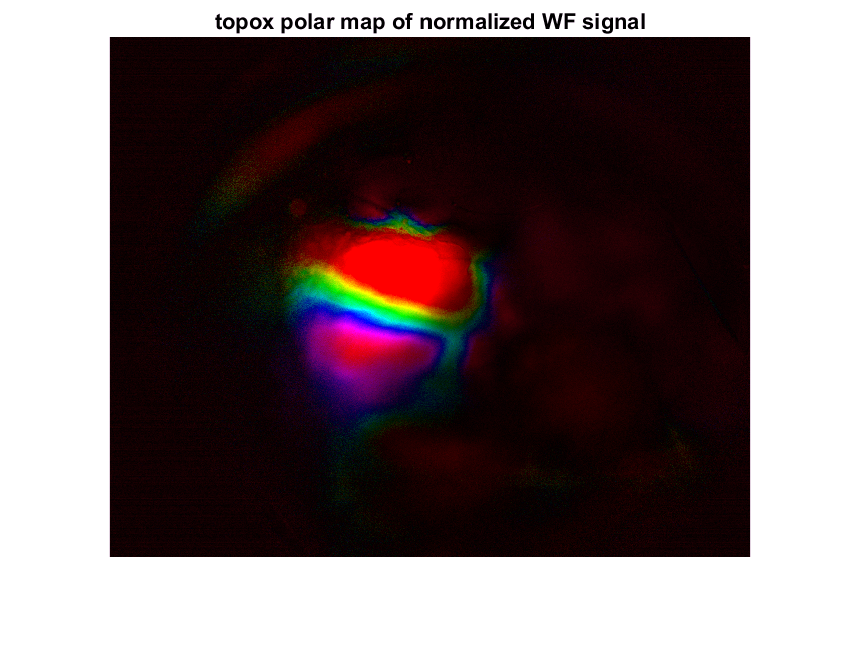

imshow(topox)
title('topox polar map of normalized WF signal')


% topoy
[f p] = uigetfile('*.mat','topoy maps file')

f = 071421_EE124RN_RIG2_TOPOYmaps.mat

p = F:\Kristen\Widefield2\071421_EE124RN_RIG2\071421_EE124RN_RIG2_TOPOY\

load(fullfile(p,f),'mapNorm','map');
topoy = polarMap(mapNorm{3});


% polar map
f2 = figure

f2 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [465.67 460.33 573.33 436.67]
       Units: 'pixels'

  Show all properties


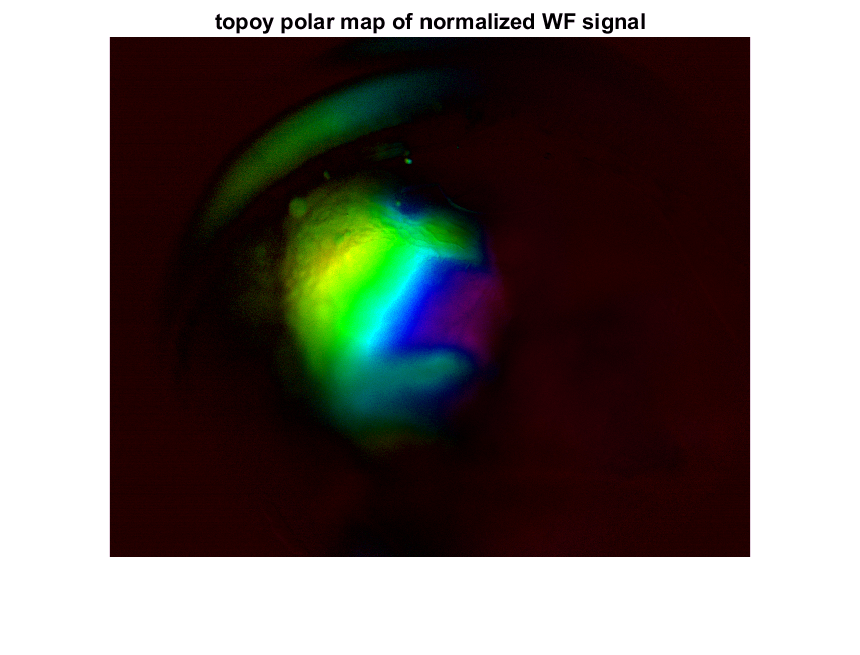

imshow(topoy)
title('topoy polar map of normalized WF signal')


%% get THRESH MAPS

[f p] = uigetfile('*.mat','maps file');

downsize = 0.25; % why resize by this factor?
load(fullfile(p,f));

Error using load
Unable to read MAT-file F:\Kristen\Widefield2\071421_EE124RN_RIG2\071421_EE124RN_RIG2_THRESH\071421_EE124RN_RIG2_THRESHmaps.mat. Not a binary MAT-file. Try load -ASCII to read as text.



%%  DOWNSIZE all 3 videos

df = dfof_bg;
% df = imresize(dfof_bg,downsize); % if green light, gets downsized in dfofMovie I think..)
topox = imresize(topox,downsize);
topoy = imresize(topoy,downsize);


% since I'm not downsizing dfof_bg anymore, is there any benefit to saving
% df here rather than loading with maps file each time?
% probably... only one var rather than more... maybe only a little faster but...

% FIG TITLES

% mouse id
load('EE124RN_subj.mat') % CHANGE NAME each time
subjName = subjData{1,1}.name; 

% date & name
%[filepath,name,ext] = fileparts('20210411T123140_25.mat'); % 277RT 041121
% [filepath,name,ext] = fileparts('20210410T195352_20.mat'); % 277RT 041021
% [filepath,name,ext] = fileparts('20210520T153642_29.mat') % 277RT 052021
% [filepath,name,ext] = fileparts('20210521T132731_36.mat'); % 277RT 0521021
% [filepath,name,ext] = fileparts('20210601T134850_11.mat'); % EE81LT 060121
% [filepath,name,ext] = fileparts('20210602T161152_12.mat'); % EE81LT 060221
% [filepath,name,ext] = fileparts('20210602T134136_38.mat') % 277RT 060221
% [filepath,name,ext] = fileparts('20210607T161721_39.mat'); % 277RT 060721
% [filepath,name,ext] = fileparts('20210615T141420_40.mat'); % 277RT 061521 
% [filepath,name,ext] = fileparts('20210704T135539_1.mat') % 305RT 070421
% [filepath,name,ext] = fileparts('20210706T124226_1.mat') % 124RN 070521
% [filepath,name,ext] = fileparts('20210706T153005_1.mat') % EE124LT 070521
% [filepath,name,ext] = fileparts('20210706T184243_2.mat') % G6H305LT 070521, 1262 trials
% [filepath,name,ext] = fileparts('20210709T134605_2.mat') % G6H305RT 070921 
% [filepath,name,ext] = fileparts('20210709T161144_2.mat') % EE124RN 070921
% [filepath,name,ext] = fileparts('20210712T130248_3.mat') % 305RT 071221
[filepath,name,ext] = fileparts('20210714T160652_3.mat') % 124RN 071421
% [filepath,name,ext] = fileparts('20210715T181200_3.mat') % 305LT 071521
% [filepath,name,ext] = fileparts('20210715T150646_2.mat') % 124LT 071521
% [filepath,name,ext] = fileparts('20210716T142250_3.mat') % 124LT 071621

datePart = name(1:8);
year = datePart(1:4);
month = datePart(5:6);
day = datePart(7:8);
date = sprintf('%s ', month, day, year);

display(date)
display(subjName)


% legend info
reigons = {'V1','LM','AL','AM','control'};
cons4Axes = {'0','3','6','12','25','50','100'};
durs4Axes = {'16','33','66','133','266'};
cons4Legend = {'0','0.03','0.063','0.125','0.25','0.5','1'};
durs4Legend = {'16 ms','33 ms','66 ms','133 ms','266 ms'};

% consThreshless4Axes = {'0','0.01','0.02','0.03'};
% dursThreshless4Axes = {'16'};
% consThreshless4Legend = {'0%','1%','2%','3%'};
% dursThreshless4Legend = {'16ms'};

% BROAD look at ACTIVITY over WHOLE FOV

titleText = sprintf('passivie viewing threshold movie \n no baseline subtraction');
clear t
t = suptitle(sprintf('%s: ',date,subjName,titleText));
%set(t, 'FontSize', 12);

clear j
for j = 1:2; % for 2 figures
    if j == 1
        % taking the average of the entire imaging field over WHOLE TIME
        mn = mean(mean(abs(df),2),1); 
        mn = squeeze(mn);
        % plot
        subplot(1,2,j)
        plot(squeeze(mn));  
        xlim([0 size(squeeze(mn),1)])  
        ylim([0 0.075])
        xlabel('frames')
        ylabel('mean dfof of entire FOV') 
        clear numFrames4title
        numFrames4title = length(mn); 
        clear numSecs4title
        numMins4title = (numFrames4title/10/60);
        title(sprintf('mean dfof of entire FOV over %0.00f mins',numMins4title))
    end 
    if j == 2
        % let's look at that average trace over a time scale closer 
        % to our AVG TRIAL LENGTH, ~2,2s / 22 imaging frames
        sqMn = squeeze(mn); % getting rid of singletons
        trSqMn = sqMn'; % transposing
        % select only 111 frames - 111/22 = roughly 5 stim presentations
        fiveStimsTrSqMn = trSqMn(1,1:111);
        numStimPresentations = 5;
        % plot
        subplot(1,2,j)
        plot(fiveStimsTrSqMn ); 
        xlim([0 length(fiveStimsTrSqMn)])
        ylim([0 0.075])
        ylabel('mean abs dfof of entire FOV') 
        xlabel('frame') 
        clear numFrames4title
        numFrames4title = length(fiveStimsTrSqMn); 
        clear numSecs4title
        numSecs4title = (numFrames4title/10);
        title(sprintf('mean dfof of entire FOV for %0.00f secs (%0.00f stim presentations)',numStimPresentations,numSecs4title)); 
    end 
end 

numFramesWholeSession = size(mn,1)


% CROP FOV


% 1st step: PICK image TO CROP from DF
% std of df gives us a general sense of how much variation there is across al trials
% we also use this to crop in next section
stdMap = std(df(:,:,1:10:end),[],3); % only take every 10 frames of df (don't need all, why?). taking std across 3rd dimension, time
figure;
range = [0 0.04];
% colormap jet
imagesc(stdMap,range)% 
clear titleText
titleText = 'stDev of dfof across time (whole thresh movie)';
title(sprintf('%s ',date,subjName,titleText))


% DO the CROP
% crop manually by picking top left and then bottom right corners of a rectangle
[xPtsCrop yPtsCrop] = ginput(2);
dfCROP = df(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1):xPtsCrop(2),:); % cropping df to be area I select 


% SHOW the CROPPED image� 
stdMap = std(dfCROP(:,:,1:10:end),[],3); 
figure
% colormap jet
imagesc(stdMap,[0 0.04])
axis equal
clear titleText
titleText = 'CROPPED stDev of dfof across time';
title(sprintf('%s ',date,subjName,titleText))


% SAVE FRAME T b/4 REDEFINE!!!
% SAVE dfCROP


% DEFINE FRAMET
% redefine imaging fraems so that 1st frame is t = zero for imaging frames
frameT = frameT-frameT(1); % in seconds

% SELECT ONSET FRAME CHUNKS
% you need to have done the 'CROP' step first because that's where dfCROP gets made

% making variable 'onset' - seconds relative to trial onset
% monitor frame rate = 60Hz, 
% trial onset = "start of stop"

clear onsets
clear i 

% making stimulus onset times relative to 1st trial onset

% take the first frame after "the mouse stops" for the FIRST time 
% (1st trial onset) - make that t = 0 for monitor time
t0 = allStop(1).frameT(1); % 1st frame for 1st trial 

for i = 1:length(allResp) % I think response period is when the stim comes on until mouse answers
    % get the first frame after the stimulus comes on, subtract
    % t0, the time of the first trial onset. So all stim onsets 
    % are realtive to 1st trial onset
    onsets(i) = allResp(i).frameT(1)-t0; % onsets is in seconds
    
end % now you have a list of the first frames during the resposne period
% in time that is relative to when the very FIRST trial started/"mouse stoppoed the ball"

display('size of onsets var =')
size(onsets)

% % for sessions where frameT stops before stim ONLY
% realNumTrials = 1949;  % don't know any other way to figure out how 
% % many trials frameT corresponds to other than running
% % onsetFrame code and seeing where is stops...
% onsets = onsets(1,1:realNumTrials);
% size(onsets)


% picking pre & post frames
numPreStimFrames = 4;
numPostStimFrames = 18;


% SELECT ONLY trials that have num pre sitm & num post stim frames around them
idxOnsetsMoreThan = find(onsets>numPreStimFrames);
idxOnsetsCanAdd = find(onsets+numPostStimFrames<max(onsets));

% for use later to index into only
idxOnsetsMeetBothCriteria = intersect(idxOnsetsMoreThan,idxOnsetsCanAdd);
onsets = onsets(idxOnsetsMeetBothCriteria);
size(onsets)


% making variable 'onsetFrame', gets the index for the 1st imaging 
% frame after the stimulus onset
clear onsetFrame
clear i

% collecting the index of the first imaging frame that follows each stim onset
for i = 1:length(onsets); % for each stim onset time/frame
  
    onsetFrame(i) = find(diff(frameT>onsets(i))); % onsetFrame is the frame index for the 
    % imaging frame frame that matches up with the onset of the stim (onsets(i))
    
end
size(onsetFrame)

% % making variable 'onsetDf'
% using onsetFrames to index into dF % take 'chunks' of video around each stim onset
clear i
clear onsetDf

for i = 1:length(onsetFrame)
    % then select only the imaging frames right before & after the onset imaging frame of each stim
    onsetDf(:,:,:,i) = dfCROP(:,:,onsetFrame(i)-numPreStimFrames:onsetFrame(i)+numPostStimFrames);
end
size(onsetDf)


% VARS 4 FIGS - need indicies for trials that meet criteria
% CONTRAST calc's
% this part needed for any loops involving looping over CONTRAST:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

conOrderedByTrial = con(trialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
% in case: conOrderedByTrial = con(idxOnsetsMeetBothCriteria)
conOrderedByTrialMeetCriteria = conOrderedByTrial(:,idxOnsetsMeetBothCriteria);
uniqueContrasts = unique(con); % for looping over contrast values later


%%  DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

durOrderedByTrial = dur(trialCond); 
durOrderedByTrialMeetCriteria = durOrderedByTrial(:,idxOnsetsMeetBothCriteria);
uniqueDurations = unique(dur);

%% CON & DUR TOGETHER

% putting together dur & con so that I can index into the trials in order w/trialCond
conAndDur = [con; dur];
% put it in order of trial presentation:
conAndDurOrderedByTrial = conAndDur(:,trialCond); % gives 2 x #trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetBothCriteria); 


% BASELINES


% get onsetDf INDEX for baseline frames 

numBaselineFrames = 4;
stimOnsetFrame = numBaselineFrames+1; % stim onset is always 1 frame ahead of the last baseline frame

clear baselineIdx
% store index of each baseline frame
for b = 1:numBaselineFrames
    baselineIdx(b) = stimOnsetFrame-b; % stim onset frames minus each basleine frame will us the 
    % correct indicies but in reverse order (in this case, 4,3,2,1 - so transpose outside the loop 
end
% this is the index for the baseline frames, regardless of what onset range was picked
baselineIdx = flip(baselineIdx);
display('baseline frame indicies are:')
baselineIdx


%% looking at the average trace over time for onsetFrame
% PRE & POST BASELINE

% mean across whole image, all trials/conditions
mnOnsetChunk = mean(squeeze(mean(squeeze(mean(onsetDf,1)))),2)';

numFrames = length(mnOnsetChunk);
numSec = (numFrames)*0.1;

figure

clear titleText
titleText = sprintf('dfof at onsets, \n all trials, all conditions');
suptitle(sprintf('%s ',date,subjName,titleText))

for j = 1:2 % pre & post baselined plots
    
    if j == 1
        
        % plot mean chunk trace
        subplot(1,2,j)
        plot(mnOnsetChunk)
        ylim([-0.006 0.01])
        xlim([0 numFrames])
        xlabel('frame') 
        ylabel('df/f')
        clear titleText
        titleText = sprintf('mean dfof across CROPped FOV for ~1 trial/%0.00f frames/%0.00f sec',numFrames4title,numMins4title);
        title(sprintf('%s ',titleText))

    end 

    if j == 2  
        
        % index into just the baseline frames of the mean chunk
        allBaseMnOnsetChunk = mnOnsetChunk(1,baselineIdx);
        % get mean for 1st 4 frames
        meanBaseOnsetChunk = mean(allBaseMnOnsetChunk,2);
        %subtract mean from each cell in mnChunkOnset vector
        baselinedMnOnsetChunk = mnOnsetChunk-meanBaseOnsetChunk;
        % plot
        clear x_axis
        x_axis = 1:length(baselinedMnOnsetChunk);
        subplot(1,2,j)
        plot(x_axis,baselinedMnOnsetChunk)
        ylim([-0.006 0.01])
        xlim([0 numFrames])
        xlabel('frame') 
        ylabel('df/f')
        clear titleText
        titleText = sprintf('mean trace across onset chunk \n w/BASELINE subtracted');
        title(sprintf('%s ',titleText))
        
    end
    
end


% PIXEL-WISE PERI-STIM (ONSETS), PRE BASELINE

% use FULL CONTRAST trials for example

clear seventhConTrials % use highest contrast, all durations
% 1st take only trials that meet critera
conOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
% then take the cth trials from that
seventhConTrials = conOrderedByTrialMeetCriteria == max(uniqueContrasts);
 
clear frames
frames = 1:size(onsetDf,3);

clear range
%range = 'not set';
range = [0 0.045]

clear frames4title
%frames4title = {'f 9';'f 10';'f 11';'f 12';'f 13';'f 14';'f 15';'f 16';'f 17';'f 18';};

figure
clear titleText
titleText = sprintf('\n peri-stim frames, no baseline subtraction, highest Con');
suptitle(sprintf('%s ',date,subjName,titleText))

clear f
for f = 1:length(frames)
        
     subplot(4,6,f)
     % show each frame
     imagesc(mean(onsetDf(:,:,frames(f),seventhConTrials),4),range); % ,range
     % st = title(sprintf('%s', frames4title{f}));
     %colormap(jet)
    
     axis off;
     axis image;
    
end

display('imagesc range is:')
range 


% CALCULATE MEAN BASELINE IMAGE
% need to subtract a mean baseline image
% get baseline frames, across all points, all trials/stimulus conditions
clear allBaselineFrameOnsetDf
allBaselineFrameOnsetDf = onsetDf(:,:,baselineIdx,:);

% now we can get selective

% get highest contrast trials only
clear seventhBaselineFrameOnsetDf
seventhBaselineFrameOnsetDf = allBaselineFrameOnsetDf(:,:,:,seventhConTrials);
% average over frames
clear meanBaselineImage
meanBaselineImage = mean(seventhBaselineFrameOnsetDf,3); % 3rd dim is frames
meanBaselineImage = squeeze(meanBaselineImage);
% average over trials
clear meanBaselineImage7thTrials
meanBaselineImage7thTrials = mean(meanBaselineImage,3); % this is the 
% "mean baseline image"

% SHOW MEAN BASELINE IMAGE
figure
clear range
range = [-0.008 0.005];
imagesc(meanBaselineImage7thTrials) % ,range
clear titleText
titleText = sprintf('\n MEAN BASELINE IMAGE, highest Con');
title(sprintf('%s ',date,subjName,titleText))

display('imagesc range is:')
range 


% plot all frames with mean baseline subtracted

% 1st take only trials that meet critera
conOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
% then take the cth trials from that
seventhConTrials = conOrderedByTrialMeetCriteria == max(uniqueContrasts);

clear range
range = [0 0.050];

figure
suptitle('peri-stim frames, w/baseline subtraction')
clear titleText
titleText = sprintf('\n peri-stim frames, BASELINED, highest Con');
suptitle(sprintf('%s ',date,subjName,titleText))

clear frames
frames = 1:size(onsetDf,3); % for every frame, subtract the baseline frame

for f = 1:length(frames)
    
    subplot(4,6,f)
  
    imagesc(mean(onsetDf(:,:,frames(f),seventhConTrials),4)-meanBaselineImage7thTrials,range) %,range
    %colormap(jet)
    
    axis off;
    axis image;

end

display('imagesc range is:')
range 


% PIXEL-WISE by CONTRAST minus BASEline

clear range
range = [0 0.04];

% which frames to plot over? stim onset frame + 10 frames
clear stimFrameRange
stimFrameRange = [stimOnsetFrame:1:stimOnsetFrame+10];

figure

clear titleText
titleText = ': peri-stimulus cortical response to varying contrasts'; % making char variables for sprintf/title later
supTit = suptitle(sprintf('%s', date, subjName, titleText));
%set(supTit, 'FontSize', 14)

clear c
for c = 1:length(uniqueContrasts);    

     clear cthTrials
    % 1st take only trials that meet critera
    conOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
    % then take cth trials from that
    cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);
     
     % whole peri stim frame range, mean across trials
     stimOnsetDf = mean(onsetDf(:,:,stimFrameRange,cthTrials),4);
         
     % BASEline trials & mean
     baselineStimOnsetDf = mean(onsetDf(:,:,baselineIdx,cthTrials),4); % baseline frames, mean across cth trials
     baselineStimOnsetDf = squeeze(baselineStimOnsetDf);  % squeeze
     meanBaselineStimOnsetDf = mean(baselineStimOnsetDf,3); % mean across baseline frames 
     
     clear allBaselinedStimOnsetDf
     
     clear f
     for f = 1:length(stimFrameRange)
         
         % baseline correction, one frame at a time
         eachBaselinedStimOnsetDf = stimOnsetDf(:,:,f)-meanBaselineStimOnsetDf;
         allBaselinedStimOnsetDf(:,:,f) = eachBaselinedStimOnsetDf; % the whole frame range, baselined
         
         % plot, one frame at a time
         % BUT we need to change the frame/subplot index eaxh row/contrast

         newF = c-1; % gonna mult f by 0 if c = 1, 1 if f = 2
         newF = newF*length(stimFrameRange); % always mult by nim frames in periStimFrameRange. So if 10 frames it's (c-1)*10, so newF = 0 if c=1, 10 if c = 2, 20 if c = 3... 60 if c = 7
         newF = f+newF; % finally, add f to get the new f index
         subplot(length(uniqueContrasts),length(stimFrameRange),newF) 
         imagesc(allBaselinedStimOnsetDf(:,:,f),range)

         axis off;
         axis image;
         
         hold on % keep plotting each new frame on same fig

     end % end f loop
    
end % end c loop

display('imagesc range is:')
range 

% PIXEL-WISE by DURATION minus BASEline

clear range
range = [0 0.04];

% which frames to plot over? stim onset frame + 10 frames
clear frameRange
frameRange = [stimOnsetFrame:1:stimOnsetFrame+10];

figure

clear titleText
titleText = ': peri-stimulus cortical response to varying durations'; % making char variables for sprintf/title later
supTit = suptitle(sprintf('%s', date, subjName, titleText));
%set(supTit, 'FontSize', 14)

clear d
for d = 1:length(uniqueDurations);    

     clear dthTrials
     % 1st take only trials that meet critera
    durOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
    % then take cth trials from that
    dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d);
     
     % whole peri stim frame range, mean across trials
     frameRangeOnsetDf = mean(onsetDf(:,:,frameRange,dthTrials),4);
         
     % BASEline trials & mean
     baselineFrameRangeOnsetDf = mean(onsetDf(:,:,baselineIdx,dthTrials),4); % baseline frames, mean across cth trials
     baselineFrameRangeOnsetDf = squeeze(baselineFrameRangeOnsetDf); 
     meanBaselineFrameRangeOnsetDf = mean(baselineFrameRangeOnsetDf,3); % mean across baseline frames & cth trials
     
     clear allBaselinedFrameRangeOnsetDf
     
     clear f
     for f = 1:length(frameRange)
         
         % baseline correction, one frame at a time
         eachBaselinedFrameRangeOnsetDf = frameRangeOnsetDf(:,:,f)-meanBaselineFrameRangeOnsetDf;
         allBaselinedFrameRangeOnsetDf(:,:,f) = eachBaselinedFrameRangeOnsetDf; % the whole frame range, baselined
         
         % plot, one frame at a time
         % BUT we need to change the frame/subplot index eaxh row/contrast
         clear newF
         newF = d-1; % gonna mult f by 0 if d = 1, 1 if d = 2...
         newF = newF*length(frameRange); % then mult by num frames in periStimFrameRange. So if 10 frames it's (c-1)*10, so newF = 0 if c=1, 10 if c = 2, 20 if c = 3... 60 if c = 7
         newF = f+newF; % finally, add f to get the new f index
         subplot(length(uniqueDurations),length(frameRange),newF) 
         imagesc(allBaselinedFrameRangeOnsetDf(:,:,f),range)

         axis off;
         axis image;
         
         hold on % keep plotting each new frame on same fig

     end % end f loop
    
end % end c loop

display('imagesc range is:')
range 


% PIXEL-WISE ALL STIM CONDITIONS
% I want to plot one big image matrix of all stim conditions... 
% I think I'll have to pick just one time point for that
% take the mean of peak frames for that "one time point"


% get PEAK FRAMES

clear peakFrameIdx
clear f
for f = 1:6 % average over n# peak frames
    % as of 6/12/21 - stop skipping 1st frame post stim
   % peakFrameIdx(f) = stimOnsetFrame+1+f; % always skip the onset frame and the one after, then take the
   % next n# of frames
   peakFrameIdx(f) = stimOnsetFrame+f;
end % now you can index the peak frames automatically if you change stim onset
display('peak frame indicies are:')
peakFrameIdx


% SHOW IMAGES for each STIM COND at PEAK response

clear range
range = [0 0.045];

clear subplotNum
subplotNum = 1;

clear fig
fig = figure % one fig all images % need fig var to alter axes later

clear titleText
titleText = ': PEAK cortical response to EACH stim condition'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

% index into trials for each combo of DUR & CON @ peak frames

 % for each contrast (row):
 for c = 1:length(uniqueContrasts)
            
    % going to plot the contrast (row) at each duration (column)
    for d = 1:length(uniqueDurations)
        
        % 1st take only trials that meet critera
        durOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        % then take cth trials from that
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d);
             
        clear cthDthTrials 
        conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetBothCriteria); 
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             
         %numTrials = sum(cthDthTrials);
         %display('num cthDth trials = ')
         
         clear cthDthPeakImage
         % get MEAN PEAK IMAGE across CTHDTH TRIALS
         allPeakFramesCthDthtrialsOnsetDf = onsetDf(:,:,peakFrameIdx,cthDthTrials);
         mnPeakFramesCthDthtrialsOnsetDf = mean(allPeakFramesCthDthtrialsOnsetDf,3);
         mnPeakFramesCthDthtrialsOnsetDf = squeeze(mnPeakFramesCthDthtrialsOnsetDf); % mean over peak frames
         mnPeakFramesMnCthDthtrialsOnsetDf = mean(mnPeakFramesCthDthtrialsOnsetDf,3); % mean over trials
         meanPeakImageCthDthTrials = squeeze(mnPeakFramesMnCthDthtrialsOnsetDf);
         
         % get BASEline IMAGE at cthdth trials
         allBaseFramesCthDthtrials = onsetDf(:,:,baselineIdx,cthDthTrials);
         meanBaseFramesCthDthtrials = mean(allBaseFramesCthDthtrials,3); % mean over frames
         meanBaseFramesCthDthtrials = squeeze(meanBaseFramesCthDthtrials);
         meanBaseFramesCthDthtrials = mean(meanBaseFramesCthDthtrials,3);
         meanBaseImageCthDthtrials = squeeze(meanBaseFramesCthDthtrials);
         
         % subtract baseline from mean peak image
         % just subtracting an image from an image here, not subtracting one baseline value from each cell in a trace
         baselinedPeakImageCthDthTrials =  meanPeakImageCthDthTrials-meanBaseImageCthDthtrials;
         
         % PLOT BASElined PEAK image
         subplot(length(uniqueContrasts),length(uniqueDurations),subplotNum)
         imagesc(baselinedPeakImageCthDthTrials,range)
         
         axis off;
         axis image;
         
         subplotNum = subplotNum+1; % use this to index subolots because it 
         % increases by every time a stim cond is plotted
         
         hold on % plotting all stim conditions on same fig, diff subplots (subplotNum)
         
    end % end d loop
    
 end % end c loop   
 
 % Give common xlabel & ylabel
han=axes(fig,'visible','off'); 
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'contrast');
xlabel(han,'duration');
             
display('imagesc range is:')
range              


% PICKING ACTIVATION IMAGE - *needs onsetDf*

% image of highest contrast & duration during peak response

clear c7d5trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetBothCriteria);
c7d5trials = conAndDurOrderedByTrialMeetCriteria(1,:) == max(uniqueContrasts) & conAndDurOrderedByTrialMeetCriteria(2,:) == max(uniqueDurations);

% within the chunk of frames in onsetDf, which do you want indexed/averaged over?
% always pick the 4th, 5th, 6th, & 7th frames following stim onset, b/c that shows
% "imprint" of vis ctx best and captures how higher value stims give not only
% greater peaks but also longer activation
clear actImIdx
% actImIdx = [stimOnsetFrame+4,stimOnsetFrame+5,stimOnsetFrame+6,stimOnsetFrame+7]; % stimOnsetFrame defined in making onsetDf code
actImIdx = peakFrameIdx;

% get all act im frames at highest c & d
clear allActImFrames
allActImFrames = onsetDf(:,:,actImIdx,c7d5trials); 
% take the average of the image across frames
clear meanActImFrames
meanActImFrames = squeeze(mean(allActImFrames,3));
meanActImFrames = mean(meanActImFrames,3);

% plot the mean peak activation image at highest stim parameters
figure
suptitle('points picked over peak activation')

range = [0 0.08]; 
imagesc(meanActImFrames,range)
axis equal
%colormap('jet');

display('imagesc range is:')
range 


% pick 5 pts - V1, motor ctx, 3 HVAs

clear xPickedPts 
clear yPickedPts 

% show activation image
% figure_1
suptitle('points picked over peak activation')

range = [0 0.08]; 
imagesc(meanActImFrames,range)
axis equal
%colormap('jet');
 
for i = 1:5
   
    hold on
    [xPickedPts(i) yPickedPts(i)] = ginput(1);
    plot(xPickedPts(i),yPickedPts(i),'*');
   
end


% SAVE this fig - CHANGE NAME & DATE
% save('070521_EE124RN_pickedPTSmap.png','figure_1','-v7.3')


% SELECT PTS from ONSET DF

RoundXpts = round(abs(yPickedPts)); %switch x & y
RoundYpts = round(abs(xPickedPts));

clear PTSdfof 
for i = 1:length(xPickedPts)
    PTSdfof(i,:,:) = onsetDf(RoundXpts(i),RoundYpts(i),:,:);
end

display('size of PTSdfof is: ')
size(PTSdfof)


% COMPARing PRE & POST BASELINE analyses for V1


% V1, PRE & POST BASEline

% from here on, PTSdfof already has the restricted trials from onsetsDf

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for all trials'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

for j = 1:2 % pre & post baseline figs

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot

        clear recomboOnePtAllFramesAllTrialMinusMeanBase
        clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
        % collect all trials over all frames for the ith point
        clear onePtAllFramesAndTrials % new var each point
        onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); 
        onePtAllFramesAndTrials = onePtAllFramesAndTrials';
        
         if j == 1 % if making pre-baselined fig
                
           % pre baseline fig
           subplot(1,2,j)
                
           clear x_axis
           x_axis = 1:size(onePtAllFramesAndTrials,2); % length of frames
           % plot one baseline corrected trace at a time
           %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase) % plot dfof the first point vs frames for each trial   
           % hold on because we're doing it for every trial on the same plot
           plot(x_axis,onePtAllFramesAndTrials)
               
           hold on
           % plot each mean trace
           clear meanOnePtAllFramesAndTrials
           meanOnePtAllFramesAndTrials = mean(onePtAllFramesAndTrials,1); % mean across trials
           % plot mean non-baselined
           plot(x_axis,meanOnePtAllFramesAndTrials,'linewidth',3)
           title('V1')
            
           ylim([-0.2 0.3]) 
           xlim([1 length(x_axis)])
           ylabel('df/f')
           xlabel('frames')
    
           ax = gca;
           x.XTick = [1:1:length(x_axis)];
                
       end 
       
       if j == 2; % if making baseline fig
            
       % for every trace, subtract the baseline value at that point from each frame value
  
           clear tr % for each trial in onePtAllFramesAndTrial
           for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
              % getting TRIAL VECTOR
              clear onePtAllFramesOneTrial % make new var for each trial
              % index into each trace/vector & save as variable
              onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
        
              % getting MEAN BASEline VALUE for each TRIAL
              clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
              % collect 4 baseline frames for tr-th ith trial
              allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
              clear mean4baseFramesOnePtOneTrial
              % get mean value of baseline values for ith point
              mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
              mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
              % BASEline CORRECTion of TRIAL VECTOR
        
              % new baseline-corrected trace for each trial
              % calulate the baselined trace for the ith trial
              onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
              % collect CORRECTed TRIAL VECTORS in matrix
              % save each tr-th baselined trace in a matrix for plotting mean later
              % (only clear this outside the loop for each point)
              recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
             % PLOT
             subplot(1,2,j) % post baseline fig
             clear x_axis
             x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
             % plot one baseline corrected trace at a time
             %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase) % plot dfof the first point vs frames for each trial   
             % hold on because we're doing it for every trial on the same plot
             plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                
             hold on % hold for next trial
                
         end % end tr loop
        
      % outside of trial loop but inside j 'if'
      
      hold on % hold for plotting mean over subplot
        
      % get mean baselined trace across all trials
      meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
   
      plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',3)
      title('baselined')
        
      ylim([-0.2 0.3]) 
      xlim([1 length(x_axis)])
      ylabel('df/f')
      xlabel('frames')

      ax = gca;
      x.XTick = [1:1:length(x_axis)];
                
       end % end 2nd if statement
       
    end % end i loop
    
end % end j loop


% V1, PRE & POST BASEline

% MEAN across TRIALS for each CONTRAST

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': df/f vs frames per contrast, \n averaged across trials'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

for j = 1:2 % pre & post baseline figs
    
    clear recomboOnePtAllFramesAllTrialMinusMeanBase

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot
        if j == 1 % if making pre-baselined fig
            
            clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
                cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
                % MEAN over trials
                meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
                % 1x51 variable that has dfof of one point averaged across trials
                % at the c-th contrast, for all frames
            
                %STDEV
                err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                % stdOverTrialsPTSdfof = (std(meanOverTrialsPTSdfof)/sqrt(trials);
                % err = stdOverTrialsPTSdfof*ones(size(meanOverTrialsPTSdfof)); % b/c just one stdev for whole trace across trials at the c-th contrast
            
                % for later group analysis - for each contrast, a trace for the i-th point
                % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
                % PLOT
                clear x_axis
                x_axis = 1:length(meanOverTrialsPTSdfof);
                subplot(1,2,j)
                errorbar(x_axis,meanOverTrialsPTSdfof,err,'linewidth',1)
                
                title('V1')
                ylim([-0.02 0.075]) 
                xlim([1 length(x_axis)])
                %st = title(sprintf('%s', reigonsTitle{r}));
                ylabel('df/f')
                xlabel ('frames')
        
                hold on % all contrast traces on one fig
                
            end % end c loop
            
            hold on
%             legend(cons4Legend)
            legend(cons4Legend)
       
        end % end 1st j if
           
        if j == 2; % if making baseline fig
           
           subplot(1,2,j)
           
           clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
                % MEAN over trials
                clear meanOverTrialsPTSdfof
                meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
                % 1x # trials variable that has dfof of one point averaged across trials
                % at the c-th contrast, for all frame
                
                % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
                % trials and we already took the mean across trials
                clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
                % collect 4 baseline frames 
                allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
                clear mean4baseFramesOnePtOneCon
                % get mean value of baseline values for ith point
                mean4baseFramesOnePtOneCon = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
                % BASEline CORRECTION
                % new baseline-corrected trace for each mean trace
                clear onePtOneConMinusMeanBase
                onePtOneConMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneCon;
        
                % COLLECT corrected traces in matrix
                % (only clear this each tine go thru j loop (new one each subplot)
                recomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = onePtOneConMinusMeanBase;
            
                %STDEV of deviation from the mean oover trials
                clear err
                % our mean trace is averaged over trials. We want to know how much the trials 
                % values varied, not how much the mean trial values vary over time...
                err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                
                % for later group analysis - for each contrast, a trace for the i-th point
                % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
                % PLOT
                clear x_axis
                x_axis = 1:length(onePtOneConMinusMeanBase);
                subplot(1,2,j)
                errorbar(x_axis,onePtOneConMinusMeanBase,err,'linewidth',1)
                ylim([-0.02 0.075])  
                xlim([1 length(x_axis)])
                title('baselined')
                % st = title(sprintf('%s', reigonsTitle{r}));
                ylabel('df/f')
                xlabel ('frames')
        
                hold on % all contrast traces on one fig
                
            end % end c loop
            
            hold on
            legend(cons4Legend)
                
       end % end 2nd j if
       
    end % end i loop
    
end % end j loop


% Is this correct??
% V1, PRE & POST BASEline
% CRF
% peak frames defined earlier

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': contrast response function'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

for j = 1:2 % pre & post baseline figs
    
    clear contStdErr
    clear crf
    clear CRFminusMeanBase

    clear i
    %for i = 1:length(xPickedPts) % for each point
    for i = 1
    
        %subplot(2,3,i) % make a subplot
        if j == 1 % if making pre-baselined fig
            
            clear c
            for c = 1:length(uniqueContrasts) % get mean peak response for each contrast (CRF)
                
                % TRIALS
                clear cthTrials
                cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
      
                % calculate CRF
                % take the i-th points over the peak frame range, for the c-th trials
                % returns 3 (frames) by # trials
                sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
                % take the mean over frames
                %returns 1 x # trials
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
                % now I need the mean over trials to get one df/f value (CRF value) representing the
                % average fluorescence over peak frames and over the c-th trials for the i-th point
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
                % now I want to collect each c-th CRF value for this point
                % creates 1 x 7 (contrasts)
                crf(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
                % STDERR
                % now I want to calulate the StdErr for each CRF point calulated above
                % (one err value for each contrast)
                % that means I want the error over trials, not over frames
                % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
                contStdErr(1,c) = stdErr; % clear this outside j loop
        
            end % end contrast loop - have full CRF for ith point
 
            % PLOTTING
            % one figure, one subplot for each point, each subplot has CRF for that poin
            % size subplot based on 7 contrasts
            subplot(1,2,j)
            % 7 contrasts for x axis
            x_axis = [1:length(uniqueContrasts)];
            crfChart = errorbar(x_axis,crf,contStdErr,'-s','MarkerSize',3,...
            'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
        
            title('V1')
            % st = title(sprintf('%s', reigons{i}));
            ylim([-0.01 0.05]) 
            % xlim([0, 8])
            xlim([0, length(uniqueContrasts)+1])
    
%             ax=crfChart.Parent;
%             ax.XMinorTick = 'on'; %more tick marks
%             set(ax, 'XTick', 0:1:8);

            clear xt
            xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
            % xt={'0'; '1' ; '2' ; '3';'4'} ; 
            set(gca,'xtick',1:7); 
            % set(gca,'xtick',1:5); 
            set(gca,'xticklabel',xt);
    
             ylabel('df/f')
             xlabel('contrast (%)')
                
        end % end 1st if statemet
             
        if j == 2; % if making baseline fig
               
            clear c
            for c = 1:length(uniqueContrasts) 
                
                % TRIALS
                clear cthTrials
                cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
                % calculate CRF
                % take the i-th points over the frame range, for the c-th trials
                % returns 3 (frames) by # trials
                clear sq5FramesOverTrialsPTSdfof
                sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
                % take the mean over frames, returns 1 x # trials
                clear meanOverFramesSq5FramesOverTrialsPTSdfof
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
                % now I need the mean over trials to get one df/f value representing the
                % average fluorescence over 3 frames and over the c-th trials for the i-th point
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
                % collect each c-th CRF value for this point
                crf(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
                % GET mean BASEline
                % the baseline for each CRF value is the mean of the baseline frames for
                % the ith point and cth contrast
                % get all frames & cth trials
                clear baselineFramesIthPtCthTrials
                baselineFramesIthPtCthTrials = squeeze((PTSdfof(i,baselineIdx,cthTrials)));
                % now have baseline frames x trials
                % take mean across trials 
                clear  meanBaselineFramesIthPtCthTrial
                meanBaselineFramesIthPtCthTrials = mean(baselineFramesIthPtCthTrials,2);
                %meanBaselineFramesIthPtCthTrials = squeeze(baselineFramesIthPtCthTrials);
                % take mean across frames
                meanBaselineFramesIthPtCthTrials = mean(meanBaselineFramesIthPtCthTrials,1);
            
                % do BASEline CORRECTION
                % subtract the cth baseline from the flourescence at each c
                CRFminusMeanBase(c) = crf(c)-meanBaselineFramesIthPtCthTrials; % clear this var in between subplots

                % STDERR
                % now I want to calulate the StdErr for each CRF point calulated above
                % (one err value for each contrast)
                % that means I want the error over trials, not over frames
                % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
                contStdErr(1,c) = stdErr; % clear outside j loop
        
            end % end contrast loop - have full baselined CRF for ith point
            
            % inside 2nd j loop still
 
            % PLOTTING
            % one figure, one subplot for each point, each subplot has CRF for that poin
            % size subplot based on 7 contrasts
            subplot(1,2,j)
            % 7 contrasts for x axis
            x_axis = 1:length(uniqueContrasts);
            crfChart = errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
            'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
            %st = title(sprintf('%s', reigons{i}));
            ylim([-0.01 0.05]) 
            % xlim([0, 8])
            xlim([0, length(uniqueContrasts)+1])
            title('baselined')
    
%             ax=crfChart.Parent;
%             ax.XMinorTick = 'on'; %more tick marks
%             set(ax, 'XTick', 0:1:8);
                
            clear xt
            xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
            % xt={'0'; '1' ; '2' ; '3';'4'} ; 
            set(gca,'xtick',1:7); 
            % set(gca,'xtick',1:5); 
            set(gca,'xticklabel',xt);
    
             ylabel('df/f')
             xlabel('contrast (%)')
     
        end % end 2nd j if statement
            
    end % end i loop
    
end % end j loop


% ALL VARS NEEDED FOR INDIVIDUAL & GROUP ANALYSIS
 
% save('071421_EE124RN_vars4IndAndGroupAnalyses.mat',...
%     'stimDetails','subjData','trialCond','subjName','date',...
%     'numPreStimFrames','numPostStimFrames','idxOnsetsMeetBothCriteria',...
%     'peakFrameIdx','stimOnsetFrame','baselineIdx','meanActImFrames',...
%     'xPickedPts','yPickedPts','RoundXpts','RoundYpts',...
%     'PTSdfof','-v7.3')